# A von Karman plate with 1:1 internal resonance

In this example, we consider a simply-supported von Karman square plate subject to harmonic excitation. Due to the geometric symmetry, the natural frequenices of the second and the third modes are the same. In other words, the system has 1:1 internal resonance between the two modes. We extract the forced response curve using SSM reduction. 

## Geometry and finite element model

We discretize the plate with 200 elements and then 606 degrees-of-freedom. The dimension of the phase space of the full system is then 1212. As we will see, the reduced-order model obtained by SSM reduction is four dimensional.

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
The circular natural frequencies of the first five modes:


omega = 1.0e+03 *

    0.3067
    0.7636
    0.7677
    1.2188
    1.5311


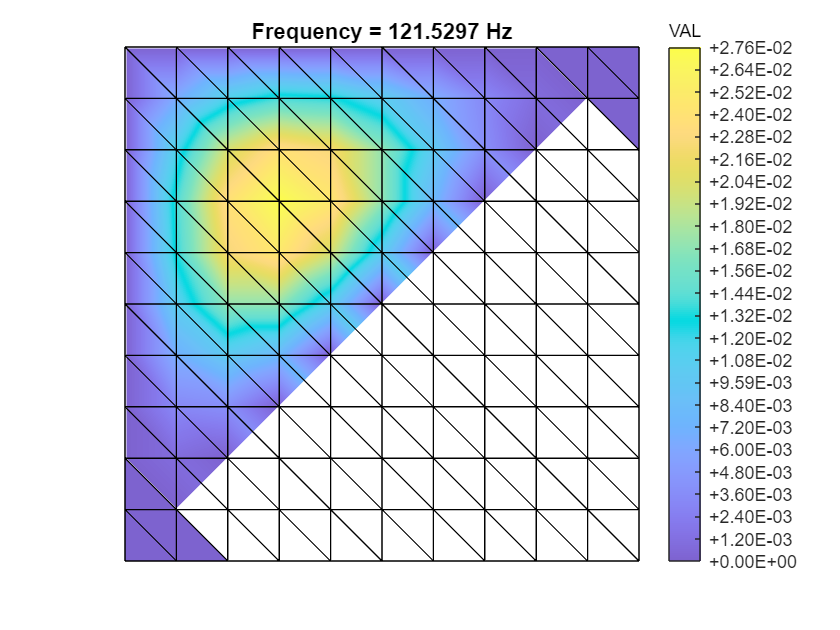

Using Rayleigh damping
Getting nonlinearity coefficients
Loaded tensors from storage
Assembling external force vector


clear all; close all; clc

l = 1; % length of domain [m]
b = 1;  % breadth of domain [m]
t = 1e-2; % thickness of plate [m]
w = 0.0; % curvature parameter (height of the midpoint relative to ends) [m]
% material properties
E     = 70e9;  % 70e9 % 200e9 % Young's modulus [Pa]
rho   = 2700; % 2700 % 7850 % density [kg/m^3]
nu    = 0.33;    % Poisson's ratio 
kappa = 1e5; % material damping modulus 1e8

% Mesh
nElements = 10;
nl = nElements;
nb = nElements;
bc = 'SSSS';
startFE = tic;
[M,C,K,fnl,~,outdof] = build_model(l,b,t,w,E,rho,nu,kappa,bc,nl,nb);

timeFE = toc(startFE);
varargout{1} = timeFE;
n  = length(M);

## Dynamical System Setup

notation = 'multiindex';
DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation',notation);

## Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.243693e-03
modal damping ratio for 2 mode is 2.181986e-03
modal damping ratio for 3 mode is 2.186754e-03
modal damping ratio for 4 mode is 2.847788e-03
modal damping ratio for 5 mode is 3.388843e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+03 *

  -0.0007 + 0.3067i
  -0.0007 - 0.3067i
  -0.0017 + 0.7636i
  -0.0017 - 0.7636i
  -0.0017 + 0.7677i
  -0.0017 - 0.7677i
  -0.0035 + 1.2188i
  -0.0035 - 1.2188i
  -0.0052 + 1.5311i
  -0.0052 - 1.5311i



## Add forcing

f_0 = zeros(n,1);
f_0(outdof(1)) = 100;
kappas  = [-1; 1];
epsilon = 1;
coeffs  = epsilon * [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas);

## Primiary resonance with IRs

**Create SSM**

S = SSM(DS);
set(S.Options, 'reltol', 0.8,'notation',notation); % 0.8 is used

**Extract FRC**

Recall that the natural frequencies of the linear modes are given by


$$\omega_{(i,j)}=\left(\frac{i^2}{l^2}+\frac{j^2}{b^2}\right)\pi^2\sqrt{\frac{D}{\rho t}}$$


where $D$ is the bending stiffness. Given $l=b$, we have $\omega_{(1,2)}=\omega_{(2,1)}$, namely the 1:1 internal resonance between the second and the third bending modes. In addition, we have $\omega_{(3,1)}=\omega_{(1,3)}=2\omega_{(1,2)}$, which implies that the higher modes (1,3) and (3,1) will also be taken as a part of the spectral subspace in the extract_FRC routine. Here we are mainly concerned with the 1:1 internal resonance. So we need to specify the spectral subspace, which can be easily done in the SSM-ep toolbox.

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

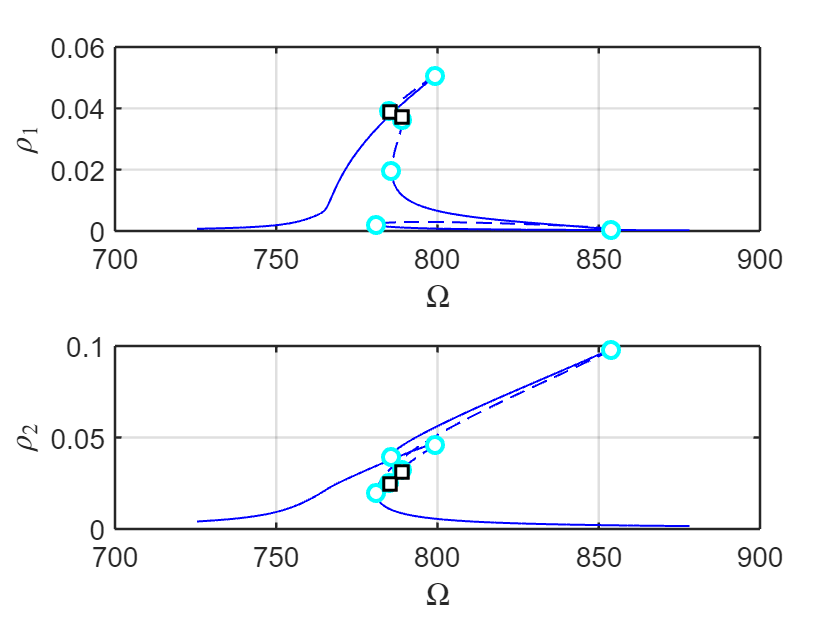

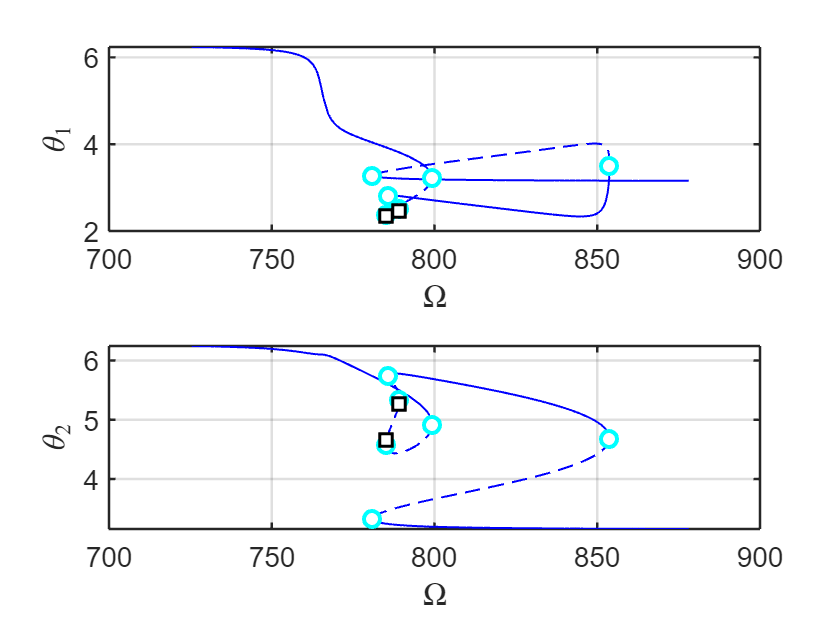

the forcing frequency 7.2541e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.2654e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.2776e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.2888e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.3007e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.3116e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.3231e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.3338e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.3449e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequency 7.3552e+02 is nearly resonant with the eigenvalue -1.6662e+00 + i7.6359e+02
the forcing frequenc

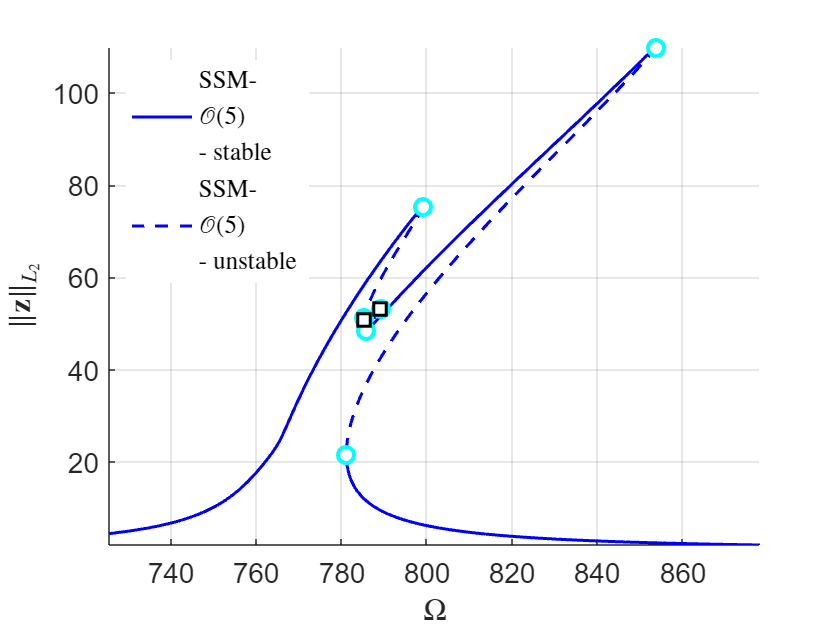

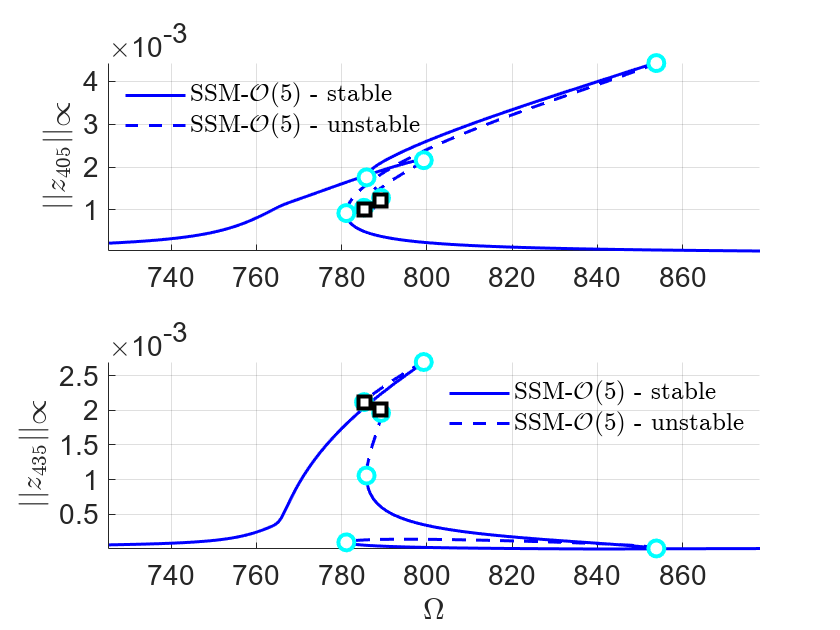

set(S.contOptions, 'PtMX', 2500, 'h_max', 5, 'h_min', 1e-4);
set(S.FRCOptions, 'initialSolver', 'fsolve');
set(S.Options, 'COMPtype', 'first');
freqrange = [0.95 1.15]*imag(D(3));
order     = 5;
resonant_modes = [3 4 5 6];
mFreq   = [1 1];
FRC_lead = S.SSM_isol2ep('isol_polar',resonant_modes, order, mFreq, 'freq', freqrange,outdof);

We explore the contribution of non-autonomous part SSM

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

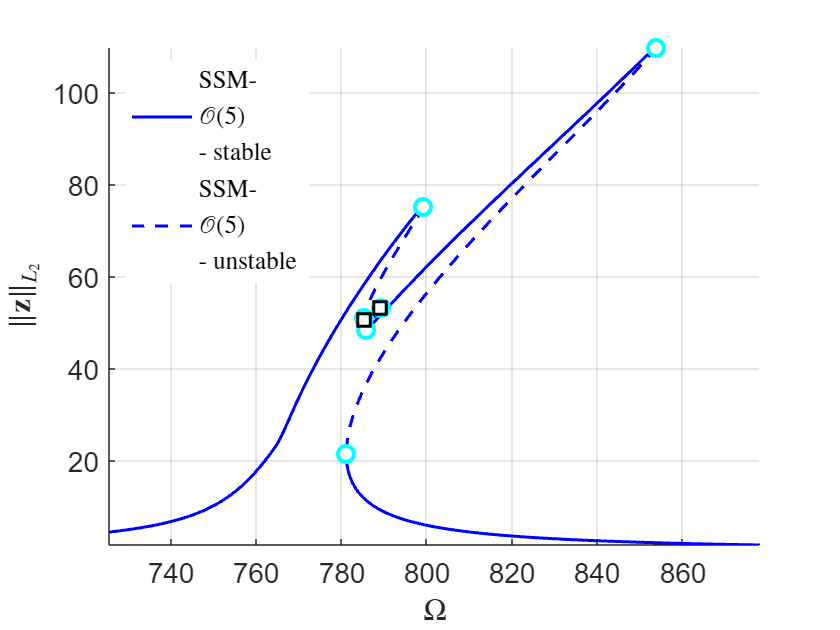

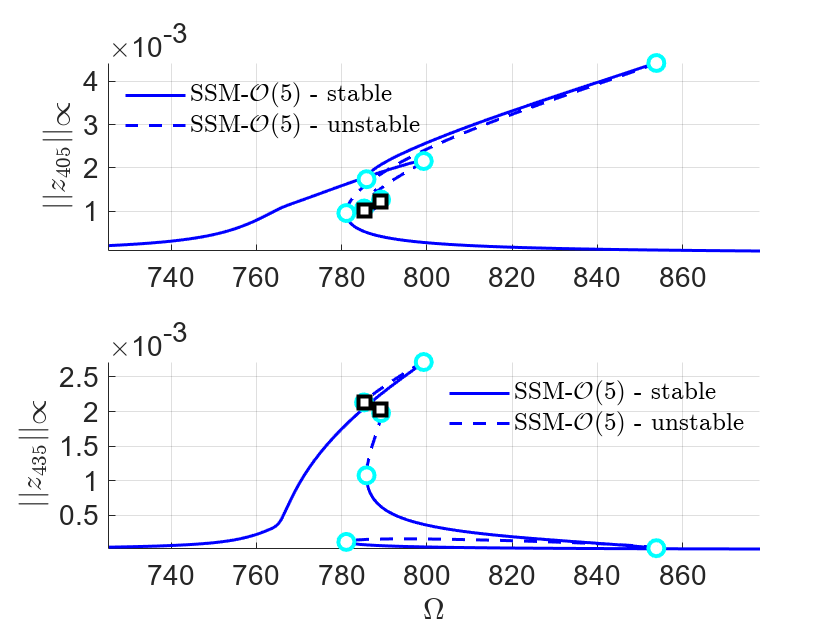

set(S.Options, 'contribNonAuto',false);
FRC_zero = S.SSM_isol2ep('isol_polar_zero',resonant_modes, order, mFreq, 'freq', freqrange,outdof);

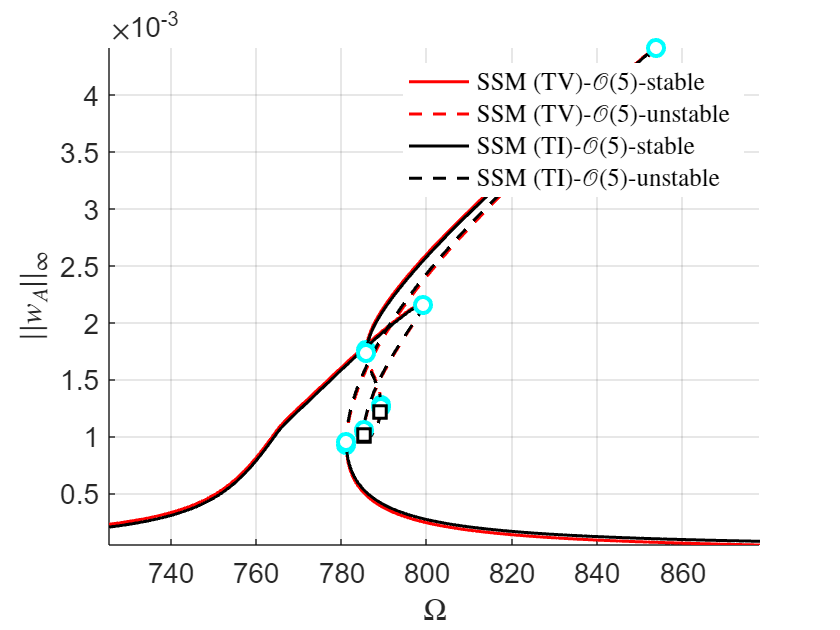

% comparision of results
FRCs = {FRC_lead,FRC_zero};
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
color = {'r','k','m','b','g'};
figure;
ax1 = gca;
for k=1:2
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    if k==1
    legs = 'SSM (TV)-$\mathcal{O}(5)$-unstable';
    legu = 'SSM (TV)-$\mathcal{O}(5)$-stable';
    else
    legs = 'SSM (TI)-$\mathcal{O}(5)$-unstable';
    legu = 'SSM (TI)-$\mathcal{O}(5)$-stable';        
    end
    hold(ax1,'on');
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||w_A||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
end
legend boxoff

### Extract of ridges and trenches 

We extract ridges of trenches of the FRS of $||w_\mathrm{A}||_{\mathcal{L}^2}$

startwa = tic

startwa = uint64
3676004641285

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

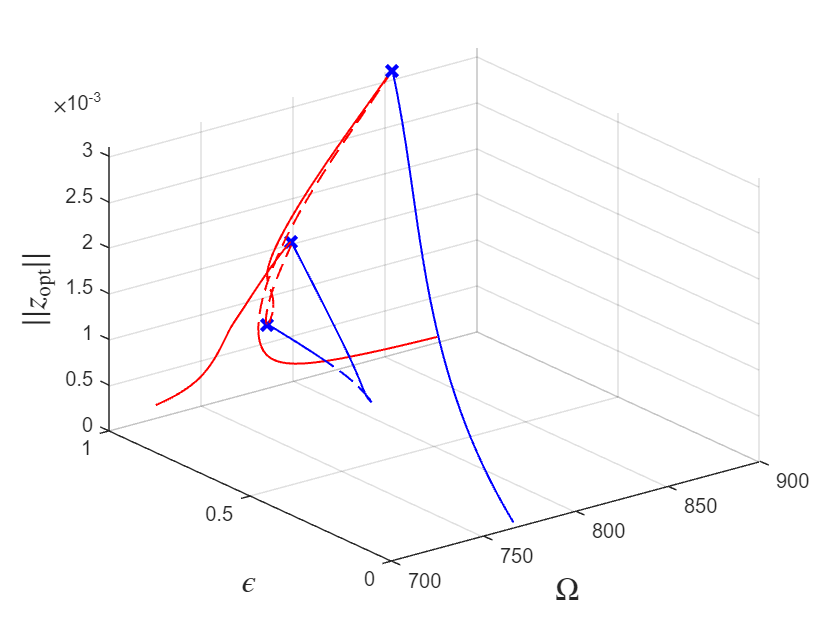

optdof = outdof(1);
set(S.contOptions, 'PtMX', 450);  % continuation setting
epsRange = [0.01 1.0]*epsilon;
parRange = {freqrange,epsRange};
sol = ep_read_solution('','isol_polar.ep',1);
set(S.FRSOptions, 'calFRS', true);
set(S.FRCOptions,'DBCobjnorm','l2','DBCstepFactor', [10 100]);
S.extract_ridges_trenches('bcssm-dof1',resonant_modes,order,mFreq,parRange,outdof(1),optdof,{sol.p,sol.x});

timings.wa = toc(startwa)

timings = struct with fields:
    wa: 64.6326


We extract ridges of trenches of the FRS of $||w_\mathrm{B}||_{\mathcal{L}^2}$

startwb = tic

startwb = uint64
3676670039202

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

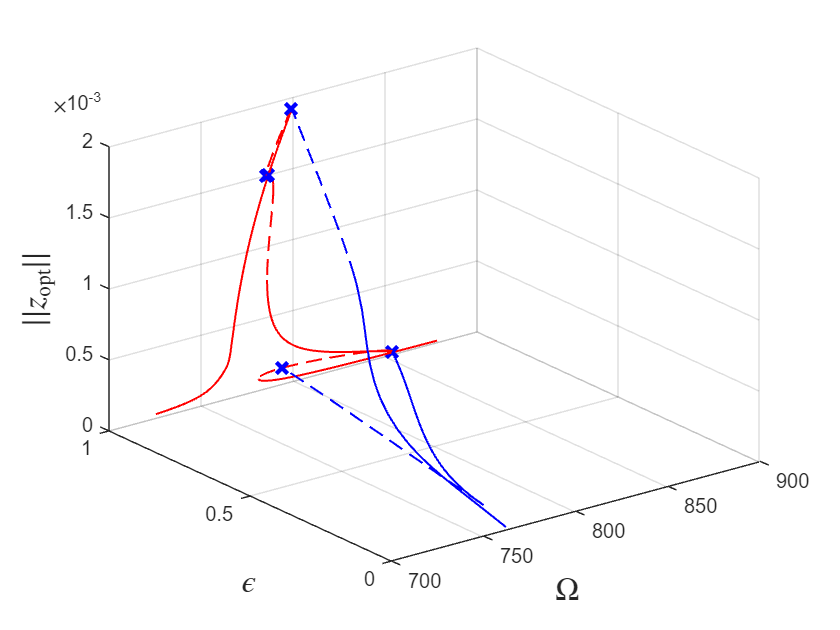

optdof = outdof(2);
S.extract_ridges_trenches('bcssm-dof2',resonant_modes,order,mFreq,parRange,outdof(2),optdof,{sol.p,sol.x});

timings.wb = toc(startwb)

timings = struct with fields:
    wa: 64.6326
    wb: 70.4455


We extract ridges of trenches of the FRS of $||E_k||_{\mathcal{L}^2}$

startek = tic

startek = uint64
3677390354212

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

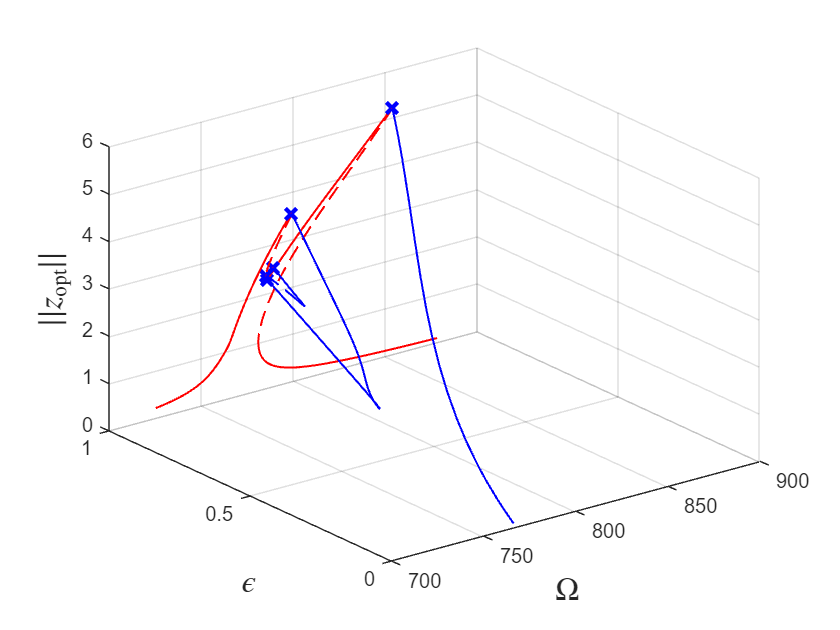

optdof = n+1:2*n;
set(S.contOptions, 'PtMX', 450, 'MaxRes', 0.5);
set(S.FRCOptions,'DBCobjweight',M/2);
S.extract_ridges_trenches('bcssm-Et',resonant_modes,order,mFreq,parRange,outdof,optdof,{sol.p,sol.x});

timings.ek = toc(startek)

timings = struct with fields:
    wa: 64.6326
    wb: 70.4455
    ek: 154.5547
